# Identifying pulsars from radio telescope data

The data in "pulsars_clean.csv" has been cleaned and is ready for use in machine learning tasks:

data = readtable('pulsars_clean.csv');

The data comes from a team who have recorded radio telescope observations from different stars. The team are working on an astronomical software application and hope to automatically distinguish between normal stars and pulsars (a rare and scientifically important type of Neutron star). Use the `summary()` command to have a quick look at the data. 

You have been tasked with trying to build a classifier which can automatically determine whether a radio telescope observation comes from a pulsar star, or a non-pulsar star. You know nothing about pulsars, or any of the features generated by radio telescope observations, but that shouldn't matter... The task only requires knowledge of machine learning techniques. Your primary objective is to find a classifier which is **as accurate as possible** (slow training/classification phases *are not* an issue in this application domain).

All aspects of your approach are for you to decide. There is no one correct solution and there are many different approaches which could attract full marks. Credit is available for any relevant aspect of the investigation you undertake, including partial investigations which don't reach a full conclusion.

Marks are available for:

- Thorough and appropriate application of the machine learning recipe taught in lectures (note the data has already been cleaned) [16 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
summary(data) %look at summary of given data

Variables:

    MeanIP: 17898×1 double

        Values:

            Min        5.8125 
            Median     115.08 
            Max        192.62 

    StdIP: 17898×1 double

        Values:

            Min        24.772 
            Median     46.947 
            Max        98.779 

    ExcKurtIP: 17898×1 double

        Values:

            Min        -1.876 
            Median    0.22324 
            Max        8.0695 

    SkewIP: 17898×1 double

        Values:

            Min       -1.7919 
            Median    0.19871 
            Max        68.102 

    MeanDMSNR: 17898×1 double

        Values:

            Min       0.21321 
            Median     2.8018 
            Max        223.39 

    StdDMSNR: 17898×1 double

        Values:

            Min        7.3704 
            Median     18.461 
            Max        110.64 

    ExcKurtDMSNR: 17898×1 do


% how many examples for 25%:
nTest = round(0.20 * size(data,1))

nTest = 3580

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =         3580           9


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =        14318           9


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'Pulsar'});
test_examples = data_test;
test_examples(:,'Pulsar') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'Pulsar'});
train_examples = data_train;
train_examples(:,'Pulsar') = [];



averages = [] %initialize empty array top store average loss 


averages =

     []




kValues = [1:2:25] %array of odd values of k between 1 and 25 inclusive

kValues =      1     3     5     7     9    11    13    15    17    19    21    23    25



for i=kValues %loop through potential values of k
    %train knn classifier on training data using KFold with 10 folds
    myknn = fitcknn(train_examples, train_labels, 'NumNeighbors',i, 'Standardize',true, 'KFold',10); %perform k-fold validation with knn  
    kFoldAverage = kfoldLoss(myknn); %calculate average loss for current value of k in the loop
    averages(end+1) = kFoldAverage; %store average loss for current value of k in the loop
end

[avgLossKnn,I] = min(averages) %find min average loss (calculate overall misclassification rate for knn)

avgLossKnn = 0.0202

I = 3

bestK = kValues(I) %find best k value to use using index of min average loss 

bestK = 5



%re-train classifier with all train data using previosuly found best value for k
mknn = fitcknn(train_examples, train_labels, 'NumNeighbors', bestK, 'Standardize',true); 

%train nb classifier on training data using KFold with 10 folds
mnb = fitcnb(train_examples, train_labels, 'KFold', 10)

mnb =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'MeanIP'  'StdIP'  'ExcKurtIP'  'SkewIP'  'MeanDMSNR'  'StdDMSNR'  'ExcKurtDMSNR'  'SkewDMSNR'}
           ResponseName: 'Y'
        NumObservations: 14318
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [N    Y]
         ScoreTransform: 'none'


  Properties, Methods



%train dt classifier on training data using KFold with 10 folds
mdt = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off', 'KFold', 10)

mdt =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'MeanIP'  'StdIP'  'ExcKurtIP'  'SkewIP'  'MeanDMSNR'  'StdDMSNR'  'ExcKurtDMSNR'  'SkewDMSNR'}
           ResponseName: 'Y'
        NumObservations: 14318
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [N    Y]
         ScoreTransform: 'none'


  Properties, Methods



%kfoldLoss(mnb, 'mode','individual')
avgLossNb = kfoldLoss(mnb) %calculate overall misclassification rate for nb

avgLossNb = 0.0556


%kfoldLoss(mdt, 'mode','individual')
avgLossDt = kfoldLoss(mdt) %calculate overall misclassification rate for dt

avgLossDt = 0.0294

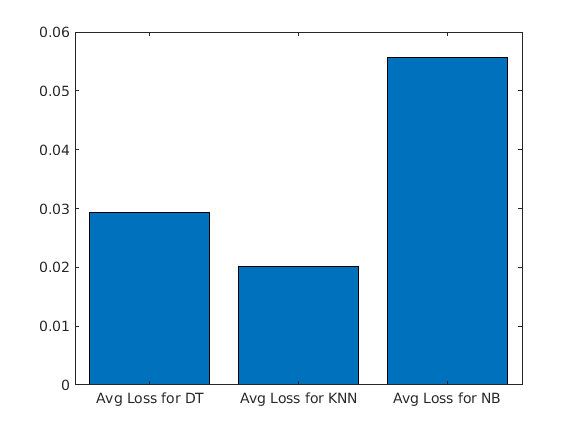



%create bar graph to visualise average loss
X = categorical({'Avg Loss for KNN', 'Avg Loss for NB', 'Avg Loss for DT'});
bar(X, ([avgLossKnn, avgLossNb, avgLossDt]))


%for loss lower is better, use min to find lowest average loss, knn is
%lower in this case so this is our winning classifier
min([avgLossKnn, avgLossNb, avgLossDt])

ans = 0.0202


%re-train nb and dt without k folds
mnb = fitcnb(train_examples, train_labels)

mnb =   ClassificationNaiveBayes
            PredictorNames: {'MeanIP'  'StdIP'  'ExcKurtIP'  'SkewIP'  'MeanDMSNR'  'StdDMSNR'  'ExcKurtDMSNR'  'SkewDMSNR'}
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [N    Y]
            ScoreTransform: 'none'
           NumObservations: 14318
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×8 cell}


  Properties, Methods


mdt = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

mdt =   ClassificationTree
           PredictorNames: {'MeanIP'  'StdIP'  'ExcKurtIP'  'SkewIP'  'MeanDMSNR'  'StdDMSNR'  'ExcKurtDMSNR'  'SkewDMSNR'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [N    Y]
           ScoreTransform: 'none'
          NumObservations: 14318


  Properties, Methods


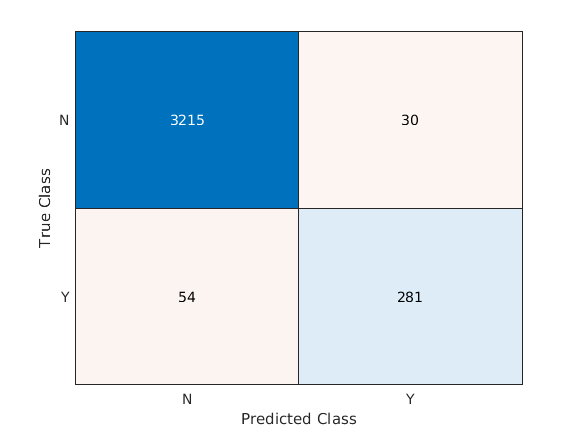



[predictionsKnn, scoresKnn] = predict(mknn, test_examples); %make prediction for test data

[cKnn, orderKnn] = confusionmat(test_labels, predictionsKnn); %generate confusion matrix

% output a labelled chart of the confusion matrix:
c_chartKnn = confusionchart(test_labels, predictionsKnn);


%calculate an overall classification accuracy
pKnn = sum(diag(cKnn)) / sum(cKnn(1:1:end))

pKnn = 0.9765

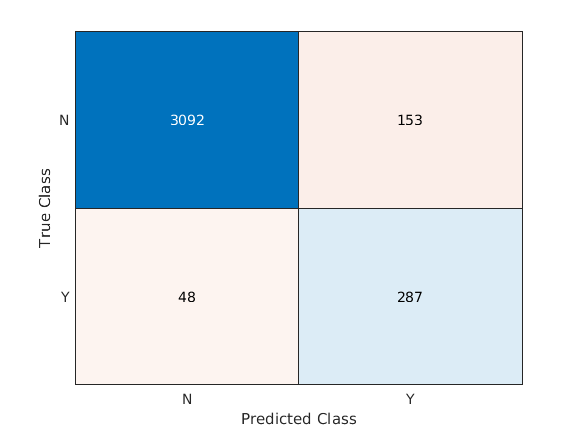




[predictionsNb, scoresNb] = predict(mnb, test_examples); %make prediction for test data

[cNb, orderNb] = confusionmat(test_labels, predictionsNb); %generate confusion matrix

% output a labelled chart of the confusion matrix:
c_chartNb = confusionchart(test_labels, predictionsNb);


%calculate an overall classification accuracy
pNb = sum(diag(cNb)) / sum(cNb(1:1:end))

pNb = 0.9439

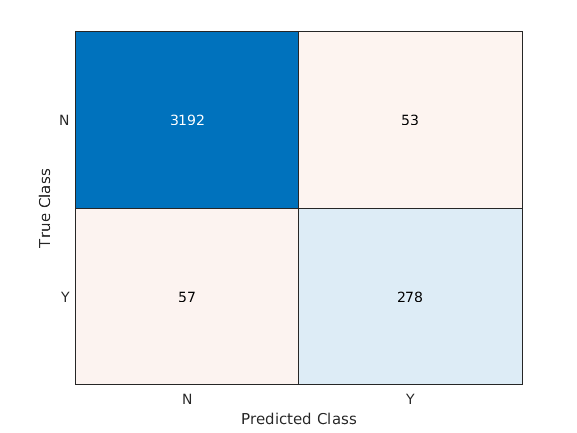




[predictionsDt, scoresDt] = predict(mdt, test_examples); %make prediction for test data

[cDt, orderDt] = confusionmat(test_labels, predictionsDt); %generate confusion matrix

% output a labelled chart of the confusion matrix:
c_chartDt = confusionchart(test_labels, predictionsDt);


%calculate an overall classification accuracy
pDt = sum(diag(cDt)) / sum(cDt(1:1:end))

pDt = 0.9693

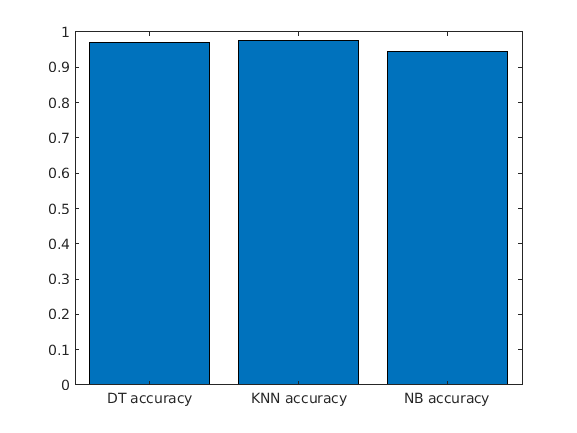



%create bar graph to visualise classification accuracy 
X = categorical({'KNN accuracy', 'NB accuracy', 'DT accuracy'});
bar(X, ([pKnn, pNb, pDt]))


%find the best accuracy
max([pKnn, pNb, pDt])

ans = 0.9765



%create ROC curve for knn
[x,y,~,AUC_knn] = perfcurve(test_labels, scoresKnn(:, 2), mknn.ClassNames(2));
AUC_knn

AUC_knn = 0.9476

plot(x,y)

hold("on")
%create ROC curve for nb
[x,y,~,AUC_nb] = perfcurve(test_labels, scoresNb(:, 2), mnb.ClassNames(2));
AUC_nb

AUC_nb = 0.9537

plot(x,y)

%create ROC curve for dt
[x,y,~,AUC_dt] = perfcurve(test_labels, scoresDt(:, 2), mdt.ClassNames(2));
AUC_dt

AUC_dt = 0.9292

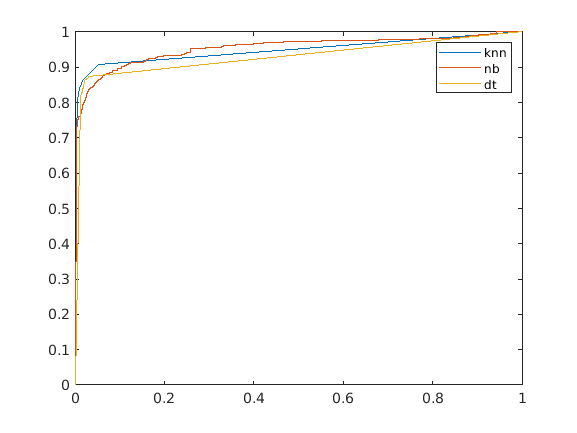

plot(x,y)

legend("knn", "nb", "dt")


%find the largest area under curve
max([AUC_knn, AUC_nb, AUC_dt])

ans = 0.9537


%I would choose knn as it has the lowest average loss, higest accuracy and
%the second largest AUC (2/3)

